# HW8P6 Test Cases

clear all
lastname = 'Key';
program_name = "HW8P6_is_pt_in_polygon_";
calling_function = str2func(program_name + lastname);

## Example 1

should return false

vertices1(1:4) = struct('x',[],'y',[]);
[vertices1.x] = deal(8,23,25,20);
[vertices1.y] = deal(20,30,12,26);
x0 = 8;
y0 = 10;

plot_polygon_and_point(x0,y0,vertices1)

is_in_poly = calling_function(x0,y0,vertices1)

is_in_poly = logical
   0


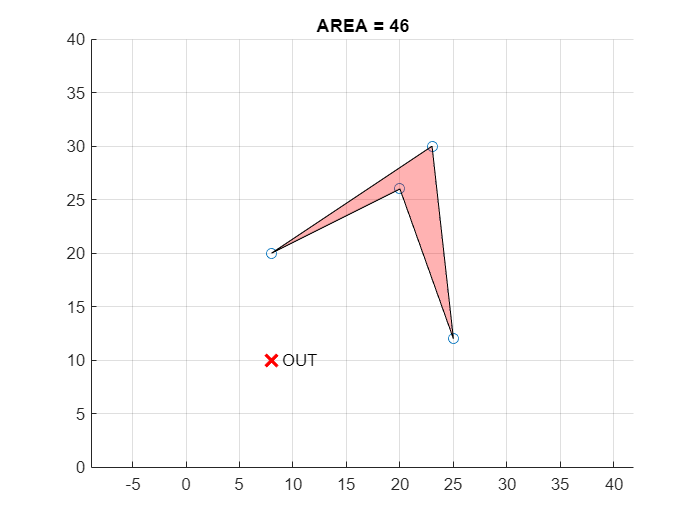


hold on
if is_in_poly
    text(x0+1,y0,'IN')
else
    text(x0+1,y0,'OUT')
end
hold off

## Example 2

should return true

x0 = 22;
y0 = 26;

plot_polygon_and_point(x0,y0,vertices1)

is_in_poly = calling_function(x0,y0,vertices1)

is_in_poly = logical
   1


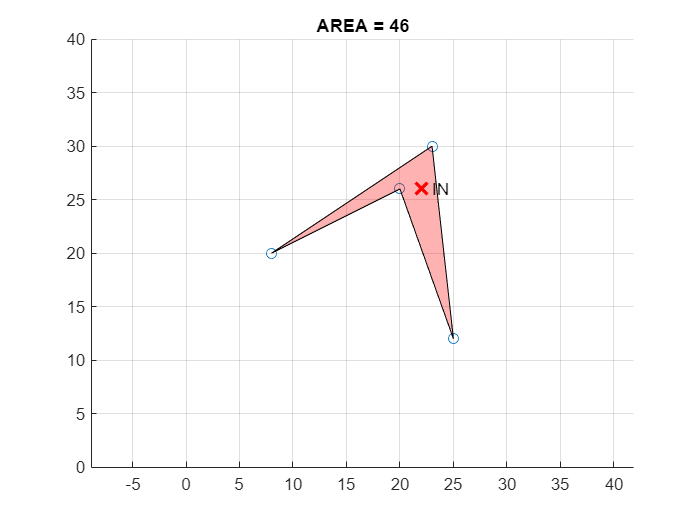


hold on
if is_in_poly
    text(x0+1,y0,'IN')
else
    text(x0+1,y0,'OUT')
end
hold off

## Example 3

should return false

vertices2(1:13) = struct('x',[],'y',[]);
[vertices2.x] = deal(35,35,21, 4, 5, 7,20, 3,18,7,21,28,29);
[vertices2.y] = deal(12,22,37,34,25,32,34,17,26,9,20,10,24);
x0 = 33;
y0 = 20;

plot_polygon_and_point(x0,y0,vertices2)

is_in_poly = calling_function(x0,y0,vertices2)

is_in_poly = logical
   1


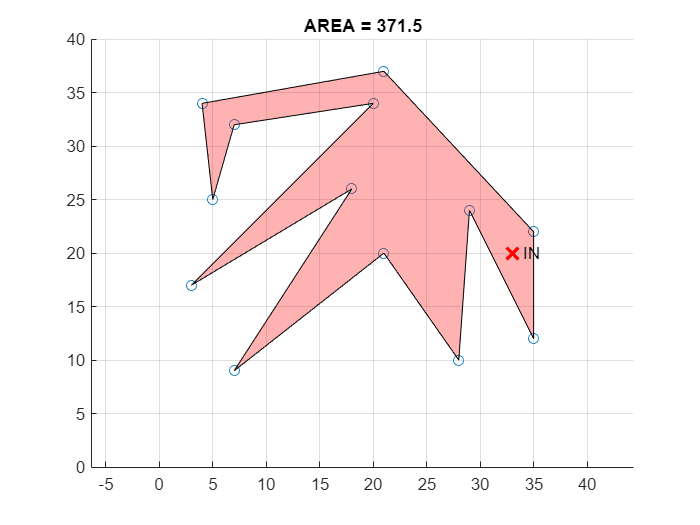


hold on
if is_in_poly
    text(x0+1,y0,'IN')
else
    text(x0+1,y0,'OUT')
end
hold off

## Example 4

should return true

x0 = 22;
y0 = 25;

plot_polygon_and_point(x0,y0,vertices2)

is_in_poly = calling_function(x0,y0,vertices2)

is_in_poly = logical
   1


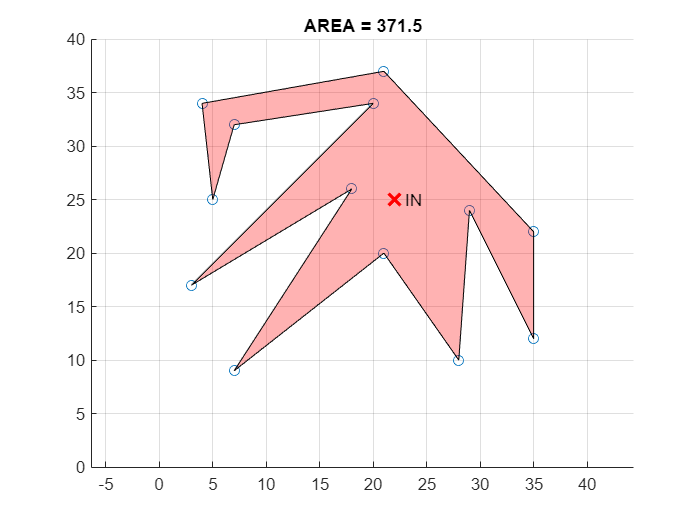


hold on
if is_in_poly
    text(x0+1,y0,'IN')
else
    text(x0+1,y0,'OUT')
end
hold off

## Example 5

should return false

x0 = 30;
y0 = 30;

plot_polygon_and_point(x0,y0,vertices2)

is_in_poly = calling_function(x0,y0,vertices2)

is_in_poly = logical
   0


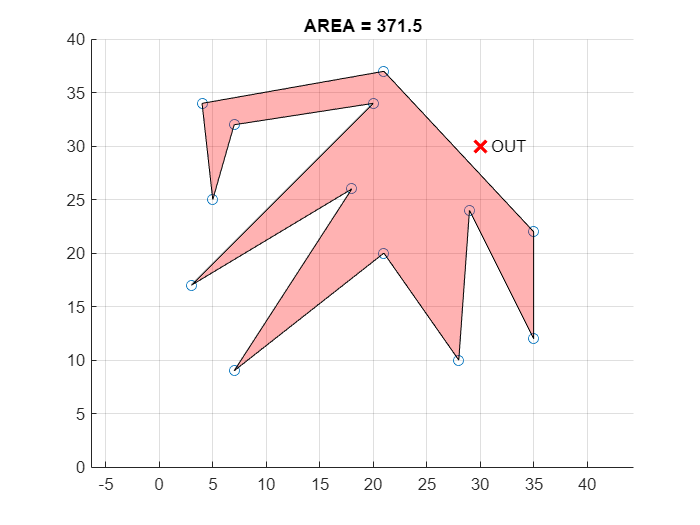


hold on
if is_in_poly
    text(x0+1,y0,'IN')
else
    text(x0+1,y0,'OUT')
end
hold off

## Example 6

should return false

x0 = 30;
y0 = 20;

plot_polygon_and_point(x0,y0,vertices2)

is_in_poly = calling_function(x0,y0,vertices2)

is_in_poly = logical
   0


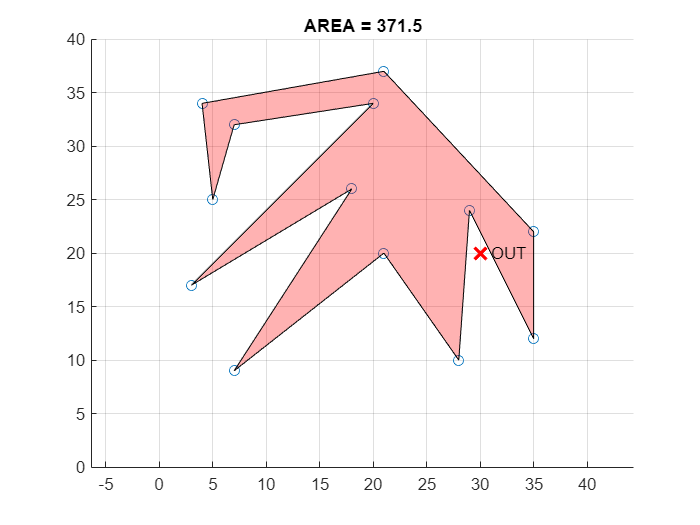


hold on
if is_in_poly
    text(x0+1,y0,'IN')
else
    text(x0+1,y0,'OUT')
end
hold off

## Example 7

should return true

vertices3(1:11) = struct('x',[],'y',[]);
[vertices3.x] = deal(35,21, 4, 5, 7,20,18,7,21,28,28);
[vertices3.y] = deal(24,37,37,25,32,32,25,10,10,10,24);
x0 = 16;
y0 = 10;

plot_polygon_and_point(x0,y0,vertices3)

is_in_poly = calling_function(x0,y0,vertices3)

is_in_poly = logical
   1


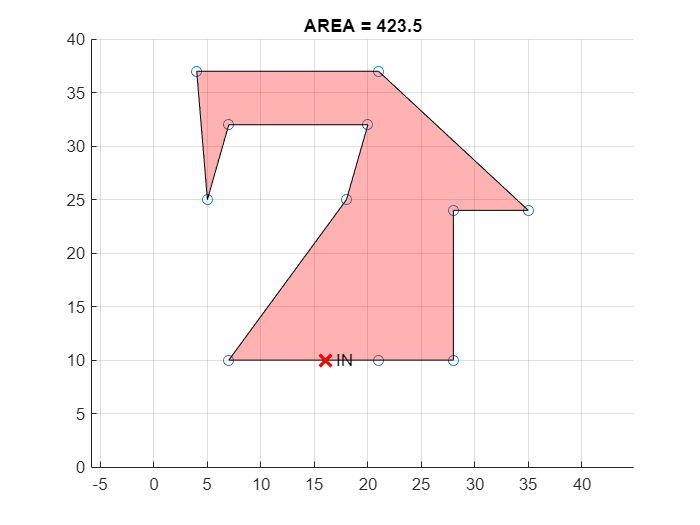


hold on
if is_in_poly
    text(x0+1,y0,'IN')
else
    text(x0+1,y0,'OUT')
end
hold off

## Example 8

should return false

x0 = 1;
y0 = 10;

plot_polygon_and_point(x0,y0,vertices3)

is_in_poly = calling_function(x0,y0,vertices3)

is_in_poly = logical
   0


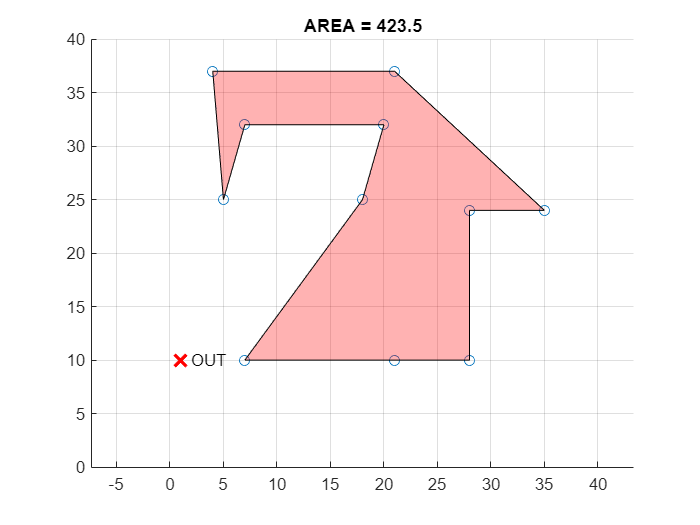


hold on
if is_in_poly
    text(x0+1,y0,'IN')
else
    text(x0+1,y0,'OUT')
end
hold off

## Example 9

should return false

x0 = 35;
y0 = 10;

plot_polygon_and_point(x0,y0,vertices3)

is_in_poly = calling_function(x0,y0,vertices3)

is_in_poly = logical
   0


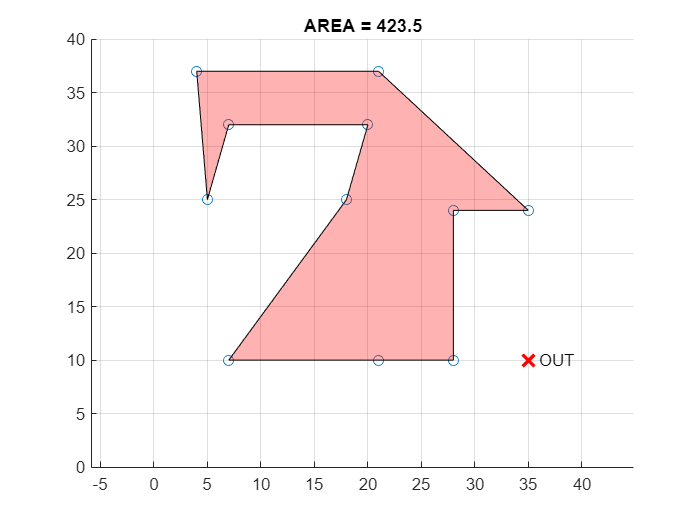


hold on
if is_in_poly
    text(x0+1,y0,'IN')
else
    text(x0+1,y0,'OUT')
end
hold off

## FREE TESTING

% Pick the vertices set
v = vertices3;

% Pick the x0 and y0 (you can also use the arrow keys to adjust the values)
x0 = 30;
y0 = 37;

plot_polygon_and_point(x0,y0,v)

is_in_poly = calling_function(x0,y0,v)

is_in_poly = logical
   0


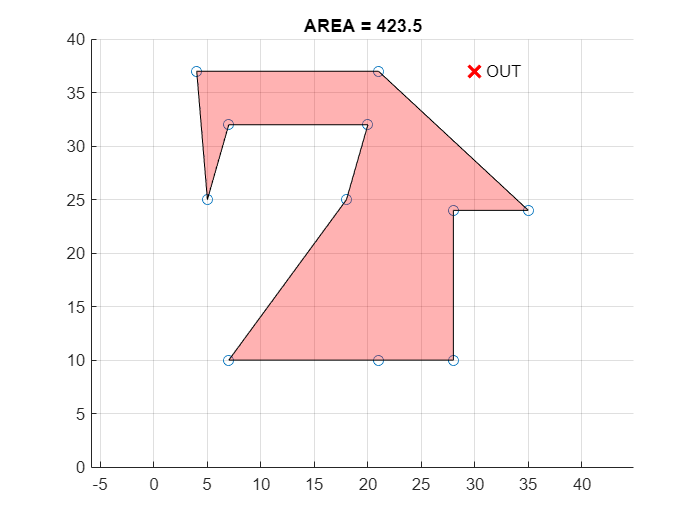


hold on
if is_in_poly
    text(x0+1,y0,'IN')
else
    text(x0+1,y0,'OUT')
end
hold off

## Plot Helper Function

function plot_polygon_and_point(x,y,v)
    close all
    figure
    hold on
    plot([v.x],[v.y],'o-')
    fill([v.x],[v.y],'red','FaceAlpha',0.3)
    plot(x,y,'rx','MarkerSize',10,'LineWidth',2)
    axis([0 40 0 40]);
    axis equal;
    grid on;
    exact_area = polyarea([v.x],[v.y]);
    title(['AREA = ' num2str(exact_area)]);
    hold off
end